clc
clear
close all

## SYSTEM MATRICES

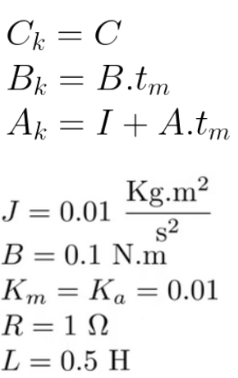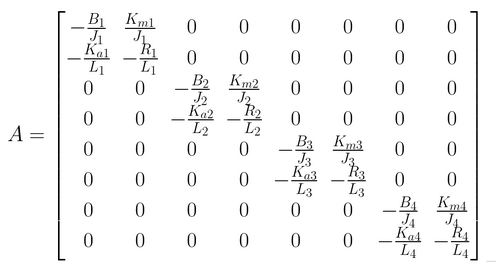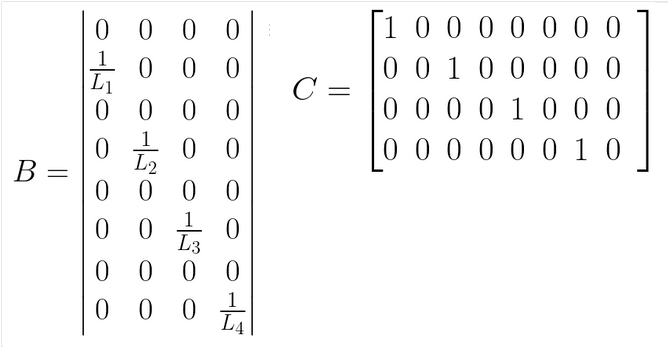

%Discretization
dt=0.001; %1ms  (Less breaks)

% Robot parameters
R_w=0.10;    %Wheel radius 10cm
Lr=0.45;    %Half car length      %90x60 car size
lr=0.30;    %Half car width
r_i=30;       %Gear ratio

%Sensor parameters
ppv=2000;
dw=2*pi/(ppv*dt); % w measuring quantizer interval (error). (rad/s) (assuming +-1pulse per sampling period)

% Process model
J_motor=0.01;
B_motor=0.002;
K_motor=0.145;
R_motor=0.93;
L_motor=1.87e-3;
% State transition matrix
A  = [-B_motor/J_motor K_motor/J_motor 0 0 0 0 0 0;
      -K_motor/L_motor -R_motor/L_motor 0 0 0 0 0 0;
      0 0 -B_motor/J_motor K_motor/J_motor 0 0 0 0;
      0 0 -K_motor/L_motor -R_motor/L_motor 0 0 0 0 ;
      0 0 0 0 -B_motor/J_motor K_motor/J_motor 0 0 ;
      0 0 0 0 -K_motor/L_motor -R_motor/L_motor 0 0;
      0 0 0 0 0 0 -B_motor/J_motor K_motor/J_motor ;
      0 0 0 0 0 0 -K_motor/L_motor -R_motor/L_motor];

A_d  = eye(8)+dt*A;  %Approximated discrete version
% Control-input matrix
B  = [0 0 0 0;
      1/L_motor 0 0 0;
      0 0 0 0;
      0 1/L_motor 0 0;
      0 0 0 0;
      0 0 1/L_motor 0;
      0 0 0 0;
      0 0 0 1/L_motor];

B_d=dt*B;   %Approximated discrete version

% Measurement matrix
C = [ 
    1 0 0 0 0 0 0 0;
    0 0 1 0 0 0 0 0;
    0 0 0 0 1 0 0 0;
    0 0 0 0 0 0 1 0];

C_d=C;

% Process disturbance variance
var=10;

## Observability

O=obsv(A,C);
rankobs=rank(O);
disp(['The observability matrix rank is: ',num2str(rankobs)])

The observability matrix rank is: 4


## Controllability

Co=ctrb(A,B);
rankco=rank(Co);
disp(['The controllability matrix rank is: ',num2str(rankco)])

The controllability matrix rank is: 4


## Continuous State Space Feedback Control Design

%Desired system with w_n=12 y zita=1/sqrt(2)
zita=1/sqrt(2);
w_n=12;
coef_lc=[1,2*zita*w_n,w_n^2];
dominantPoles=roots(coef_lc);
poles=5*max(real(dominantPoles))*ones(8,1);
poles(1:2)=dominantPoles;
poles(7:8)=poles(7:8)*1.5 %Because place method requires eigenvalue multiplicity lower than number of inputs.

poles =   -8.4853 + 8.4853i
  -8.4853 - 8.4853i
 -42.4264 + 0.0000i
 -42.4264 + 0.0000i
 -42.4264 + 0.0000i
 -42.4264 + 0.0000i
 -63.6396 + 0.0000i
 -63.6396 + 0.0000i


%K matrix
K=place(A,B,poles)  %size 4,8       %size(x),size(u)

K =     0.1704   -0.7424   -0.0455   -0.0156   -0.0829   -0.0285   -0.0000   -0.0000
   -0.0740   -0.0254   -0.0262   -0.8099   -0.0433   -0.0149    0.0000    0.0000
   -0.0429   -0.0147    0.0959    0.0329   -0.1435   -0.8502   -0.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.2005   -0.7320


%Get kr
kr=-inv(C/(A-B*K)*B)  %size 4, 4     %size(y),size(u) 

kr =     0.3180   -0.0457   -0.0833   -0.0000
   -0.0744    0.1205   -0.0435    0.0000
   -0.0431    0.0963    0.0026   -0.0000
    0.0000    0.0000   -0.0000    0.3482


## Observer design

obs_poles=50*max(real(dominantPoles))*ones(8,1);
obs_poles(5:8)=60*max(real(dominantPoles));
obs_poles

obs_poles =  -424.2641
 -424.2641
 -424.2641
 -424.2641
 -509.1169
 -509.1169
 -509.1169
 -509.1169


%%Determine observer gain L
L=place(A',C',obs_poles)'    %size 8,4        size(x),size(y)

L =   435.8547    0.0000    0.0000    0.0000
 -136.9506   -0.0000   -0.0000   -0.0000
    0.0000  435.8547    0.0000    0.0000
    0.0000 -136.9506    0.0000   -0.0000
   -0.0000    0.0000  435.8547    0.0000
   -0.0000   -0.0000 -136.9506   -0.0000
   -0.0000    0.0000    0.0000  435.8547
         0   -0.0000   -0.0000 -136.9506


L_d=dt*L; %Approximated discrete L matrix

## Kalman Observer Design

% Process noise covariance matrix Rv
Q_kal  = 1e-4*eye(8);

% Process noise measurement matrix Rw
R_kal = 100*eye(4);

## Reference

dtref=1e-4;
Lref=3.33; %So each signal lasts 10 seconds
tvecaux=0:dtref:Lref;

%Rise part
aref=-4*pi/Lref^3;
bref=6*pi/Lref^2;
cref=0;
dref=0;
y1vec=f(tvecaux,aref,bref,cref,dref);

%Constant part
y2vec=2*pi*ones(1,length(tvecaux));

%Fall part
aref=4*pi/Lref^3;
bref=-6*pi/Lref^2;
cref=0;
dref=2*pi;
y3vec=f(tvecaux,aref,bref,cref,dref);

%Complete function
yvec=[y1vec y2vec y3vec]/8/pi;
tvec=[tvecaux Lref+dtref+tvecaux 2*Lref+2*dtref+tvecaux];
restvec=zeros(size(yvec));
% dataref=[tvec' yvec'];
ttraj=[tvec tvec(end)+tvec+dtref 2*tvec(end)+tvec+dtref 3*tvec(end)+tvec+dtref 4*tvec(end)+tvec+dtref];
vxtraj=[yvec restvec restvec restvec yvec/sqrt(2)];
vytraj=[restvec yvec restvec yvec yvec/sqrt(2)];
wtraj=[restvec restvec yvec yvec restvec];
dataxref=[ttraj' vxtraj'];
datayref=[ttraj' vytraj'];
datawref=[ttraj' wtraj'];

function y=f(t,a,b,c,d)
    y=a*t.^3+b*t.^2+c*t+d;
end